# Modeling and Optimizing a Battery Charging Profile

In this project, we will use MATLAB to model a battery charging profile. We will fit real lithium‑ion battery data in MATLAB, compute energy transfer through numerical integration, and analyze key performance characteristics such as charge‑rate behavior and efficiency losses.

**Suggested Tasks**

- Given data for a lithium-ion battery charging profile, use MATLAB to fit the equation for voltage provided in the Project Description.

- Plot the following curves: voltage vs. time, current vs. time, and power vs. time.

- Use integration to compute the total energy delivered to the battery (area under power-time curve).

- Analyze the rate of voltage change at different intervals (calculate derivatives), compute the time to reach 80% and 100% charge, and compute the energy lost due to resistance.

## Task 1: Fit the voltage equation to a lithium-ion battery profile

Description of the data: Single cell cycled to failure at a temperature chamber of 30 degrees Celsius. In each cycle, the battery is fully charged until it reaches 3.6 V and fully discharged when it reaches 2 V.  

Purpose: obtain data from a single cell to a analyze its performance over time.

1 cycle: Rest, charge the battery, constant voltage, rest, and discharge the battery.

%STEP 1- load the battery dataset into MATLAB memory and show the first five rows
dataFile=matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile)
load("singleCellLifeTimeData.mat")
head(data,5)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    ___________


%STEP 2-Select one battery cycle and only keep the period of time in which the battery was being charged
%The following code selects solely the battery cycle with index 1
cycleData=data(data.Cycle_Index==1,:);
%To identify the cycling phases we will use the batteryTestDataParser. This
%function enables raw data visualization, aids in identifying anomalies, and prepare high-quality data.
%The bParser is an object-parser will analyze Cycle 1
bParser=batteryTestDataParser(cycleData);
%Indicates the use of the column called current when current values are
%needed
bParser.CurrentVariable='Current';
%Indicates the use of the column called voltage when voltage values are
%needed
bParser.VoltageVariable="Voltage";
%Indicates the use of the column called DateTime when time information is
%needed
bParser.TimeVariable="DateTime";
%Indicates the use of the column called Cycle Index to know which cycle a
%measurement belongs to
bParser.CycleIndexVariable='Cycle_Index';
%Indicates the use of the column called Step Index to identify the different
%steps inside the cycle
bParser.StepIndexVariable='Step_Index';
%Use segmentData to identify the cycling phase and mode that each data
%point belongs to, and flag invalid data points. 
segmentedRawDataTable=segmentData(bParser);
%Select only the data in which the battery was being charged 
chargeData=segmentedRawDataTable(segmentedRawDataTable.CyclingPhases=="Charge",:); 
% Convert time to seconds starting at charging beginning (makes the exact
% time in which the battery started charging to be time=0 seconds)
chargeData.DateTime = seconds(chargeData.DateTime - chargeData.DateTime(1));

%STEP 3- fit the voltage equation to the selected data 
%The x variable corresponds to time and the y variable corresponds to
%voltage. Obtain these variables from charging data
t=chargeData.DateTime;
V=chargeData.Voltage;
%The battery is fully charged at 3.6 V so Vmax=3.6 V
Vmax=3.6;
%Define the capacitor charging equation V(t)=Vmax�(1−e^(−t/RC)), also known
%as the RC charging equation. 
%Tau equals RC and it represents the time it takes for a capacitor to reach approximately 63.2% of its max voltage.  Our only unknown is tau.  
rcEquation=fittype(@(tau, t) Vmax*(1-exp(-t/tau)), 'independent', 't', 'coefficients', 'tau');
%Give an initial guess for tau and create fitting options
opts=fitoptions(rcEquation);
opts.StartPoint=1000;
opts.Lower=0.0000001;
opts.Upper = 100000;
%Syntax:[fitobject,gof]=fit(x,y,fitType,fitOptions)
[fitobject,gof]=fit(t,V,rcEquation,opts);
%Display fitted time constant
fitobject

fitobject =      General model:
     fitobject(t) = Vmax*(1-exp(-t/tau))
     Coefficients (with 95% confidence bounds):
       tau =      0.2279  (0.2096, 0.2462)

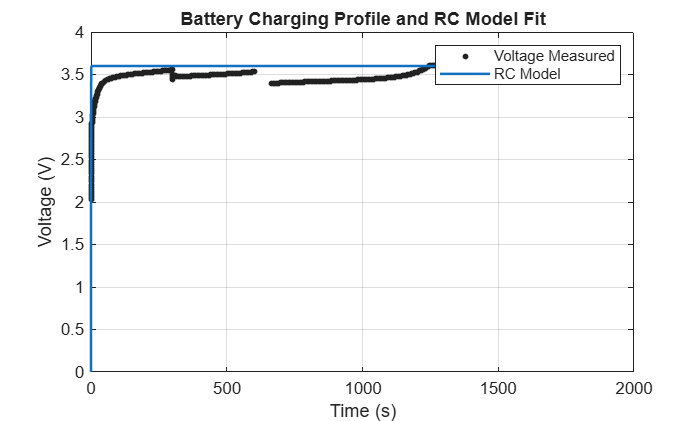

%STEP 4-Plot the data and the fitted curve in the same figure 
plot(fitobject,t,V);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Battery Charging Profile and RC Model Fit');
legend('Voltage Measured','RC Model');
grid on;
% To save the visualization as a PNG image.
exportgraphics(gcf, 'TASK1_RCMODELFIT_MANUAL.png', 'Resolution', 300);


%STEP 5- Display the goodness of fit statistics
gof

gof = struct with fields:
           sse: 45.6319
       rsquare: 0.2294
           dfe: 611
    adjrsquare: 0.2294
          rmse: 0.2733


This curved was created using the Curve Fitter APP 

The equation used is: 

                                        
$$V(t)=V_{0}+\left(V_{\max}-V_{0}\right)\left(1-e^{-t/\tau}\right)$$


Note: Vmax = 3.6 V and Vo = 2.0326 V

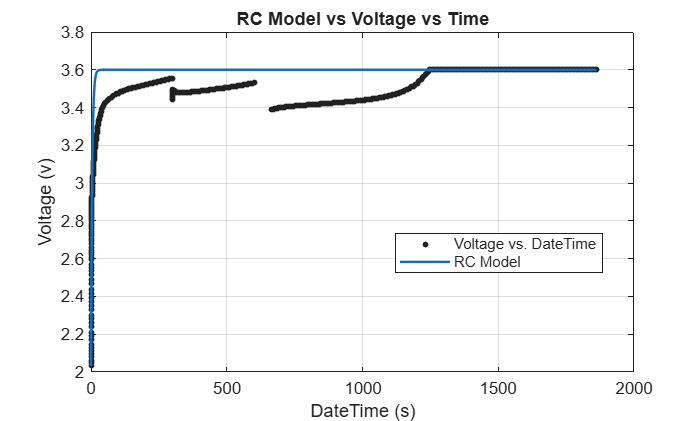

% Create RC Model Fit Plot

DateTime = chargeData.DateTime;
Voltage = chargeData.Voltage;


[fitresult, gof] = CREATE_RC_CURVE(DateTime, Voltage);

xlim("auto")
ylim("auto")
legend(["Voltage vs. DateTime", "RC Model"], "Interpreter", "none", "Location", "none", "Position", [0.5642 0.3519 0.2968, 0.0941])

title("RC Model vs Voltage vs Time")
xlabel("DateTime (s)", "Interpreter", "none")
ylabel("Voltage (v)", "Interpreter", "none")

% To save the visualization as a PNG image.
exportgraphics(gcf, 'TASK1_RCMODELFIT_CURVEFITTERAPP.png', 'Resolution', 300);

%STEP 5- Display the goodness of fit statistics

% Create variable tau = RC
% RC parameters
tau = fitresult.tau;
R = chargeData.Internal_Resistance(1);
C = tau / R;

% Goodness-of-fit table
FitStats = table( ...
    tau, ...
    gof.rsquare, ...
    gof.adjrsquare, ...
    gof.rmse, ...
    gof.sse, ...
    'VariableNames', ...
    {'Tau_s','Rsquare','AdjustedRsquare','RMSE','SSE'});

FitStats

FitStats = 1×5 table
    Tau_s     Rsquare    AdjustedRsquare     RMSE       SSE 
    ______    _______    _______________    _______    _____

    4.4285    0.72945        0.72945        0.16192    16.02


Note: R^2 is 0.7294

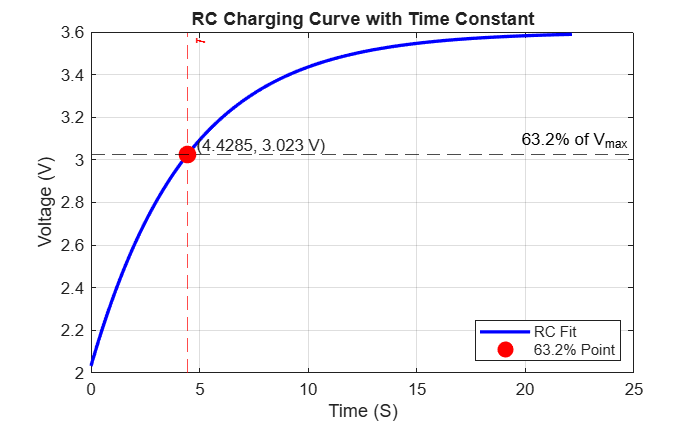

% Tau the time constant

% Declare Variables
tau = 4.4285;
Vo = chargeData.Voltage(1);
Vmax = 3.6;

t = linspace(0,5*tau,200);
%voltage = Vmax*(1-exp(-t/tau)); DELETE THIS
voltage = Vo + (Vmax-Vo).*(1-exp(-t/tau));

% 63.2 % out of 100%
%V63 = 0.632 * Vmax; Use this line to use tau from the original model
%starting at 0V

%OR
% Use this when using Vo = 2.0326 V
V63 = Vo + 0.632*(Vmax - Vo);

figure
plot(t,voltage,'b','LineWidth',2)
hold on

% Mark the 63.2% point
plot(tau,V63,'ro','MarkerSize',10,'MarkerFaceColor','r')

% Draw reference lines
xline(tau,'--r','\tau')
yline(V63,'--k','63.2% of V_{max}')

text(tau,V63,...
    sprintf('  (%.4f, %.3f V)',tau,V63),...
    'VerticalAlignment','bottom')

xlabel('Time (S)')
ylabel('Voltage (V)')
title('RC Charging Curve with Time Constant')
grid on
legend('RC Fit','63.2% Point','Location','southeast')

% To save the visualization as a PNG image.
exportgraphics(gcf, 'TASK1_RCCURVE_TIMECONSTANT.png', 'Resolution', 300);

## Task 2: Plot the electrical terms that express how energy moves in a circuit

The following code generates three different plots to visualize the current, voltage, and power with respect to one charging cycle. The final visualization corresponds to a single figure containing the subplots: 

        Voltage vs. time

        Current vs. time

        Power vs. time

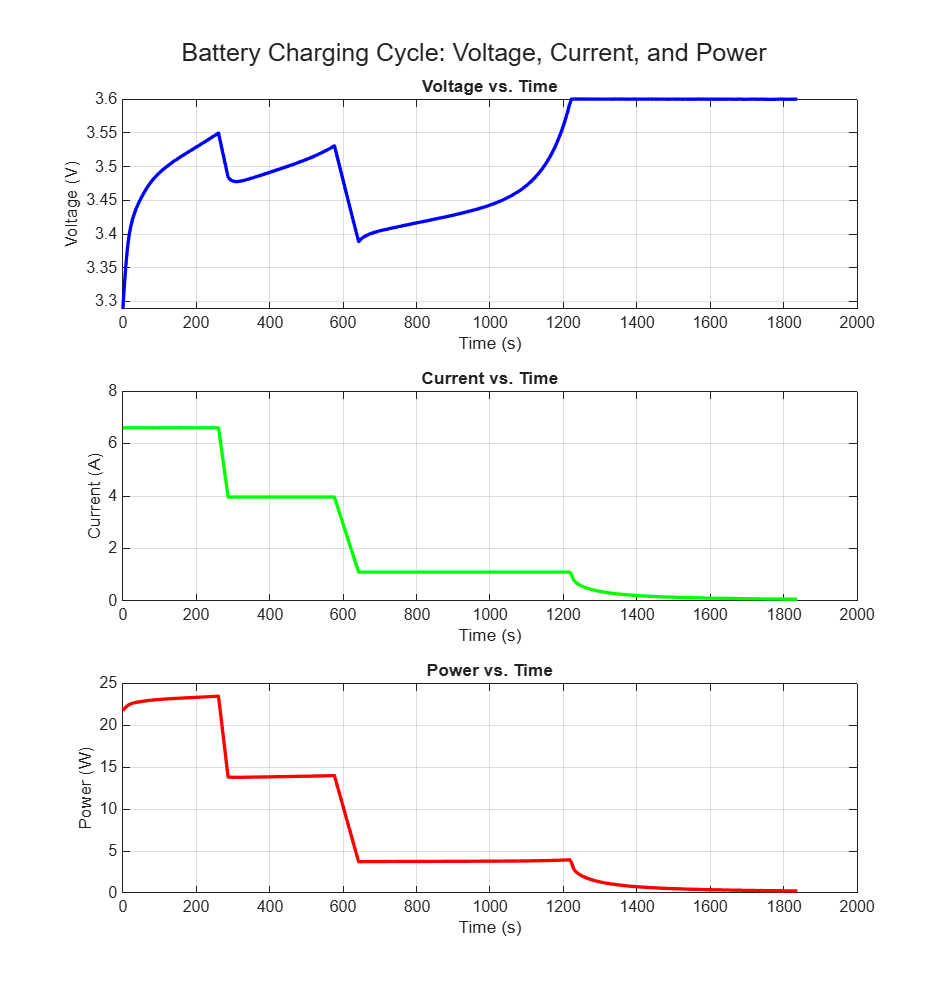

chargeData=segmentedRawDataTable(segmentedRawDataTable.CyclingPhases=="Charge" & segmentedRawDataTable.Cycle_Index==1 & segmentedRawDataTable.IsValid==true,:);
chargeData.DateTime = seconds(chargeData.DateTime - chargeData.DateTime(1));
% Filter out the irregular data points.

% STEP 1
% Create a figure handle and initialize the first subplot. Plot voltage vs.
% time.
fig = figure;
% To create the figure handle.
subplot(3, 1, 1);
% Because general format is subplot(number_of_rows, number_of_columns,
% position), 3 rows refer to the 3 different subplots (Voltage vs. Time,
% Current vs. Time, and Power vs. Time), the 1 column stacks the three
% subplots vertically satisfying the condition that they be presented as
% a visualization with one figure, and lastly, the position is 1 referring
% to the first subplot Voltage vs. Time. 
plot(chargeData.DateTime, chargeData.Voltage, 'b-', 'LineWidth', 2)
% Because general format is plot(x, y, 'type of color + line style',
% 'optionally enlarge line width', value for linewidth), for subplot 1
% time is the x axis, voltage is the y axis, color of the line of plot is 
% self-dictated as blue, and width of line is increased to 2 for better
% visibility. 
xlabel('Time (s)');
% To name the x-axis as its represented value time.
ylabel('Voltage (V)'); 
% To name the y-axis as its represented value voltage. 
title('Voltage vs. Time');
% To name the title
grid on;
% To display grid lines for visibility. 

% STEP 2
% Use a second subplot to plot current vs. time.
subplot(3, 1, 2);
% Once again, general format remains the same, only change: the position is 
% 2 now and refers to the second subplot
% Current vs. Time. 
plot(chargeData.DateTime, chargeData.Current, 'g-', 'LineWidth', 2)
% General format remains the same, changes: y axis is now current, 
% self-dictated color of line is now green.
xlabel('Time (s)');
% To name the x-axis as its represented value time.
ylabel('Current (A)');
% To name the y-axis as its represented value current.
title('Current vs. Time');
% To name the title
grid on;
% To display grid lines for visibility.

% STEP 3
% Use a third subplot to plot power vs time.
% Hint: P = I * V where I is current in amps. You will first
% need to compute power before you can create this plot.
chargeData.Power = chargeData.Voltage .* chargeData.Current; 
% Compute power by using element-by-element operator '.*' and the 
% equation P = I * V. 
subplot(3, 1, 3);
% Once again, general format remains the same, only change: the position is 
% 3 now and refers to the third subplot
% Power vs. Time. 
plot(chargeData.DateTime, chargeData.Power, 'r-', 'LineWidth', 2)
% General format remains the same, changes: y axis is now power, 
% self-dictated color of line is now red.
xlabel('Time (s)');
% To name the x-axis as its represented value time.
ylabel('Power (W)');
% To name the y-axis as its represented value power.
title('Power vs. Time');
% To name the title.
grid on;
% To display grid lines for visibility.

sgtitle('Battery Charging Cycle: Voltage, Current, and Power');
% To have a cumulative title summarizing the purpose of all 3 subplots.

set(gcf, 'position', [100, 50, 800, 900]);
% Change dimensions of graph for visibility.

exportgraphics(fig, 'TASK2_PLOTS_VOLTAGECURRENTPOWER_VS_TIME.png', 'Resolution', 300);

% To save the visualization as a PNG image.

## Task 3: Compute analytical results

**3.1 Conduct a rate-of-change analysis by computing the derivative at key intervals in the voltage data:**

 **Compute the voltage derivative:**

The rate of change of voltage with respect to time.     

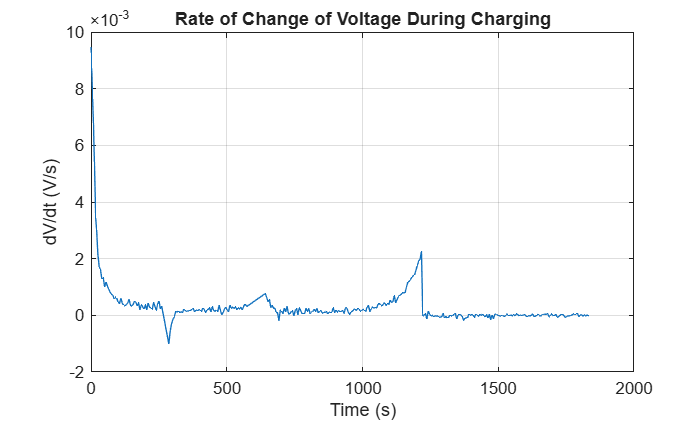

% Variables
time = chargeData.DateTime;
% Raw data
dVdt = chargeData.("dV/dt");

% dVdt tells us how quickly the voltage is charging at each
% point in time during the charging cycle.

figure
plot(time, dVdt)
xlabel('Time (s)')
ylabel('dV/dt (V/s)')
title('Rate of Change of Voltage During Charging')
grid on

% To save the visualization as a PNG image.
exportgraphics(gcf, 'TASK3_DVDT_VS_TIME.png', 'Resolution', 300);


%xlim([-8 195])
%ylim([-0.020 0.071])

% UNCOMMENT THE LINE OF CODE BELOW TO SEE ALL THE DATA OF CYCLE 1
%openvar('chargeData');

%openvar("dVdt")

**Compute the rate of voltage at different key time intervals:**

% Rate of voltage change at key intervals

% Computed dV/dt from voltage and time
dVdt_Compute = gradient(chargeData.Voltage, chargeData.DateTime);

% dV/dt provided in the raw dataset
dVdt_Raw = chargeData.("dV/dt");

% Representative indices
idxBeginning = 1;
idxMiddle = round(length(dVdt_Compute)/2);
idxEnd = length(dVdt_Compute);

% Computed values
dVdt_beginning = dVdt_Compute(idxBeginning);
dVdt_middle = dVdt_Compute(idxMiddle);
dVdt_end = dVdt_Compute(idxEnd);
dVdt_Cmax = max(dVdt_Compute);
dVdt_Cmin = min(dVdt_Compute);

% Raw-data values
dVdt_beginning_RD = dVdt_Raw(idxBeginning);
dVdt_middle_RD = dVdt_Raw(idxMiddle);
dVdt_end_RD = dVdt_Raw(idxEnd);
dVdt_max = max(dVdt_Raw);
dVdt_min = min(dVdt_Raw);

% Display computed values
fprintf('\nComputed dV/dt values\n');


Computed dV/dt values


fprintf('Beginning: %.6f s, dV/dt = %.6f V/s\n', ...
    time(idxBeginning), dVdt_beginning);

Beginning: 0.000000 s, dV/dt = 0.009005 V/s



fprintf('Middle: %.6f s, dV/dt = %.6f V/s\n', ...
    time(idxMiddle), dVdt_middle);

Middle: 952.148200 s, dV/dt = 0.000164 V/s



fprintf('End: %.6f s, dV/dt = %.6f V/s\n', ...
    time(idxEnd), dVdt_end);

End: 1837.158000 s, dV/dt = 0.000159 V/s



fprintf('Maximum computed dV/dt: %.6f V/s\n', dVdt_Cmax);

Maximum computed dV/dt: 0.009005 V/s


fprintf('Minimum computed dV/dt: %.6f V/s\n', dVdt_Cmin);

Minimum computed dV/dt: -0.002202 V/s



% Display raw-data values
fprintf('\nRaw-data dV/dt values\n');


Raw-data dV/dt values


fprintf('Beginning: %.6f s, dV/dt = %.6f V/s\n', ...
    time(idxBeginning), dVdt_beginning_RD);

Beginning: 0.000000 s, dV/dt = 0.009459 V/s



fprintf('Middle: %.6f s, dV/dt = %.6f V/s\n', ...
    time(idxMiddle), dVdt_middle_RD);

Middle: 952.148200 s, dV/dt = 0.000018 V/s



fprintf('End: %.6f s, dV/dt = %.6f V/s\n', ...
    time(idxEnd), dVdt_end_RD);

End: 1837.158000 s, dV/dt = -0.000038 V/s



fprintf('Maximum raw-data dV/dt: %.6f V/s\n', dVdt_max);

Maximum raw-data dV/dt: 0.009459 V/s


fprintf('Minimum raw-data dV/dt: %.6f V/s\n', dVdt_min);

Minimum raw-data dV/dt: -0.001013 V/s


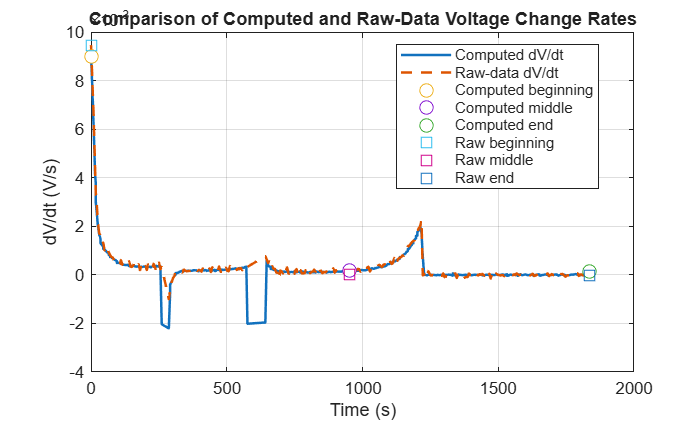


% Plot computed and raw-data dV/dt

figure
plot(time, dVdt_Compute, 'LineWidth', 1.5)
hold on
plot(time, dVdt_Raw, '--', 'LineWidth', 1.5)

% Mark representative computed values
plot(time(idxBeginning), dVdt_beginning, 'o', ...
    'MarkerSize', 8, 'MarkerFaceColor', 'auto')

plot(time(idxMiddle), dVdt_middle, 'o', ...
    'MarkerSize', 8, 'MarkerFaceColor', 'auto')

plot(time(idxEnd), dVdt_end, 'o', ...
    'MarkerSize', 8, 'MarkerFaceColor', 'auto')

% Mark representative raw-data values
plot(time(idxBeginning), dVdt_beginning_RD, 's', ...
    'MarkerSize', 8)

plot(time(idxMiddle), dVdt_middle_RD, 's', ...
    'MarkerSize', 8)

plot(time(idxEnd), dVdt_end_RD, 's', ...
    'MarkerSize', 8)

xlabel('Time (s)')
ylabel('dV/dt (V/s)')
title('Comparison of Computed and Raw-Data Voltage Change Rates')
legend('Computed dV/dt', ...
       'Raw-data dV/dt', ...
       'Computed beginning', ...
       'Computed middle', ...
       'Computed end', ...
       'Raw beginning', ...
       'Raw middle', ...
       'Raw end', ...
       'Location', 'best')
grid on
hold off

% To save the visualization as a PNG image.
exportgraphics(gcf, 'TASK3_DVDT_COMPUTED_VS_RAW.png', 'Resolution', 300);



%xlim([-17 167])
%ylim([-0.048 0.413])

The values calculated at the beginning, middle, and end represent the instantaneous rate of voltage change at different stages of charging. 

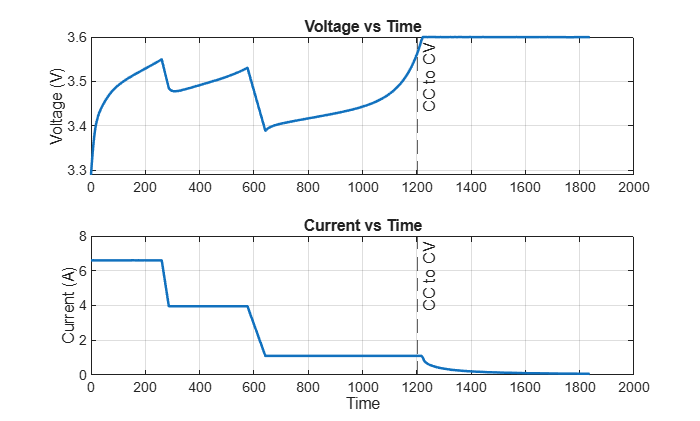

% Constant current vs constant voltage
time    = chargeData.DateTime;
voltage = chargeData.Voltage;
current = chargeData.Current;
% Raw data
%dVdt    = chargeData.("dV/dt");

% Transition from CC to CV
% CV begins when voltage reaches 99% of its maximum value
% Voltage Threshold = 0.99*3.60=3.564
voltageThreshold = 0.99 * max(voltage);

idx_transition = find(voltage >= voltageThreshold, 1, 'first');

% Indices for each charging region
idx_CC = 1:idx_transition-1;
idx_CV = idx_transition:length(time);


figure

subplot(2,1,1)
plot(time, voltage, 'LineWidth', 1.5)
hold on
xline(time(idx_transition), '--', 'CC to CV')
ylabel('Voltage (V)')
title('Voltage vs Time')
grid on

subplot(2,1,2)
plot(time, current, 'LineWidth', 1.5)
hold on
xline(time(idx_transition), '--', 'CC to CV')
xlabel('Time')
ylabel('Current (A)')
title('Current vs Time')
grid on

% To save the visualization as a PNG image.
exportgraphics(gcf, 'TASK3_CC_VS_CV_VOLTAGECURRENT.png', 'Resolution', 300);

Verification between CC and CV plots:

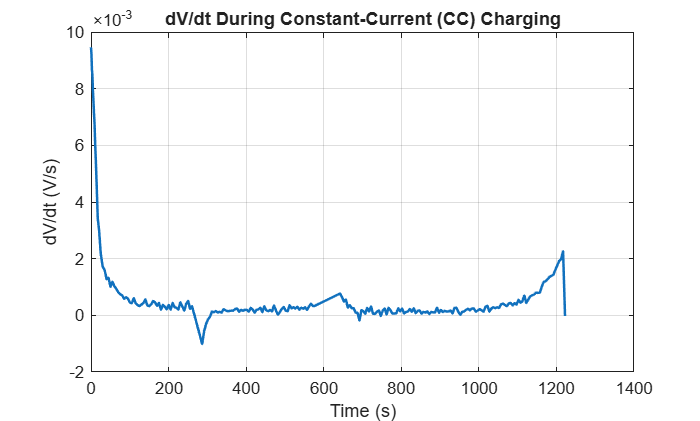

% Keep only valid charge data
validCharge = chargeData.IsValid & ...
    chargeData.CyclingPhases == "Charge";

data = chargeData(validCharge,:);

% Variables
time = data.DateTime;
dVdt = data.("dV/dt");

% Constant-Current (CC) data
CC = data.CyclingModes == "CC";

timeCC = time(CC);
dVdtCC = dVdt(CC);

% Constant-Voltage (CV) data
CV = data.CyclingModes == "CV";

timeCV = time(CV);
dVdtCV = dVdt(CV);

% Plot dV/dt during CC charging
figure
plot(timeCC, dVdtCC,'LineWidth',1.5)
xlabel('Time (s)')
ylabel('dV/dt (V/s)')
title('dV/dt During Constant-Current (CC) Charging')
grid on

% To save the visualization as a PNG image.
exportgraphics(gcf, 'TASK3_DVDT_CC_PHASE.png', 'Resolution', 300);

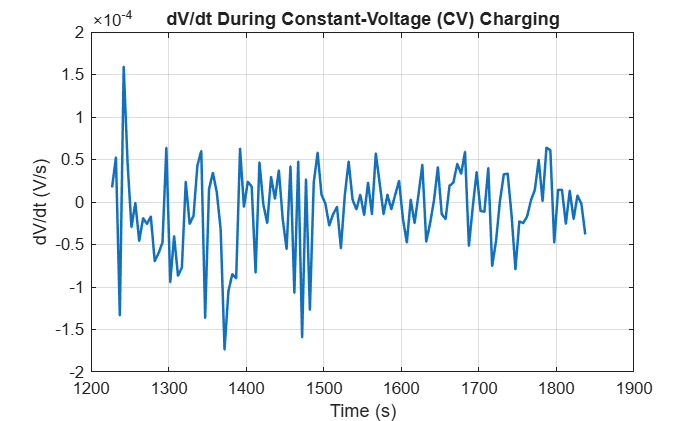


% Plot dV/dt during CV charging
figure
plot(timeCV, dVdtCV,'LineWidth',1.5)
xlabel('Time (s)')
ylabel('dV/dt (V/s)')
title('dV/dt During Constant-Voltage (CV) Charging')
grid on

% To save the visualization as a PNG image.
exportgraphics(gcf, 'TASK3_DVDT_CV_PHASE.png', 'Resolution', 300);

**3.2 Compute the time required to reach 80% and 100% charge:**


% Declare Variables
% Maximum charge capacity
% When battery reaches 100% approximately 3.6V
maxCapacity = max(chargeData.Charge_Capacity);

% 80% of the maximum capacity
capacity80 =0.8 * maxCapacity;

% Find the data point when 80% and 100% are reached:

% Find when the battery reaches 80%
charge80 = find(chargeData.Charge_Capacity >= capacity80, 1, 'first');
% Find when the battery reaches 100%
charge100 = find(chargeData.Charge_Capacity >= maxCapacity, 1, 'first');

% Convert data point position to time
time80 = time(charge80);
time100 = time(charge100);

% Display the times
fprintf('Time to reach 80%% charge =%.6f s\n', time80);

Time to reach 80% charge =572.098800 s


fprintf('Time to reach 100%% charge =%.6f s\n', time100);

Time to reach 100% charge =1837.158000 s


**3.2.1 The following code displays a visual plot of the charging process, highlighting the points at which the battery reaches 80% and 100% charge. The 100% charge level represents the maximum charge capacity recorded during Cycle1.**

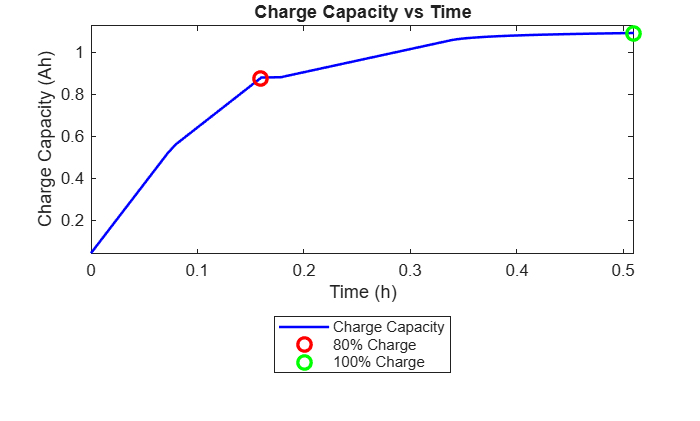

% Plot Charge Capacity vs Time

figure

% Convert time from seconds to hours
time_Hours = time/3600;
time_80Hours = time80/3600;
time_100Hours = time100/3600;

plot(time_Hours, chargeData.Charge_Capacity, 'b', 'LineWidth', 1.5)
% To keep the current graph and add plots to it
hold on

% Mark the 80% charge point
% The red circle identifies the point at which the battery reaches 80%
% charge.
plot(time_80Hours, chargeData.Charge_Capacity(charge80), 'ro', 'MarkerSize', 8, 'LineWidth', 2)

% Mark the 100% charge point
% The green circle identifies the point at which the battery reaches 100%
% charge.
plot(time_100Hours, chargeData.Charge_Capacity(charge100), 'go', 'MarkerSize', 8, 'LineWidth', 2)

% Display the points when the battery reaches 80% and 100% charge

text(time_80Hours + 30, chargeData.Charge_Capacity(charge80), + 0.01,'80%', 'Color', 'black')

text(time_100Hours + 30, chargeData.Charge_Capacity(charge100), +0.01, '100%', 'Color', 'black')


% Display the plot
xlabel('Time (h)')
ylabel('Charge Capacity (Ah)')
title('Charge Capacity vs Time')
legend('Charge Capacity', '80% Charge' , '100% Charge', 'Location', 'southoutside')

xlim([min(time_Hours) max(time_Hours)])
ylim([0.04 1.13])

% To save the visualization as a PNG image.
exportgraphics(gcf, 'TASK3_CHARGECAPACITY_80_100.png', 'Resolution', 300);

**3.3 Compute the total energy delivered to the battery by using integration to calculate the area under the power-time curve.**

The instantaneous power tells us how fast electrical energy is being delivered to the battery at each moment during the charging process.

Power is:

                                                
$$P\left(t\right)=V\left(t\right)I\left(t\right)$$


Then calculate the total energy delivered:

                                                
$$E=\int_{t_i }^{t_f } P\left(t\right)\mathrm{dt}$$


% Calculate the Energy delivered

% First calculate instantaneous power in watts
% Use (.*) 
power = voltage .* current;

% Calculate the area under the power-time curve
% Which is the total energy delivered in joules
energy = trapz(time, power);

% Display the result
fprintf('Total energy delivered = %.2f J\n', energy);

Total energy delivered = 13712.89 J


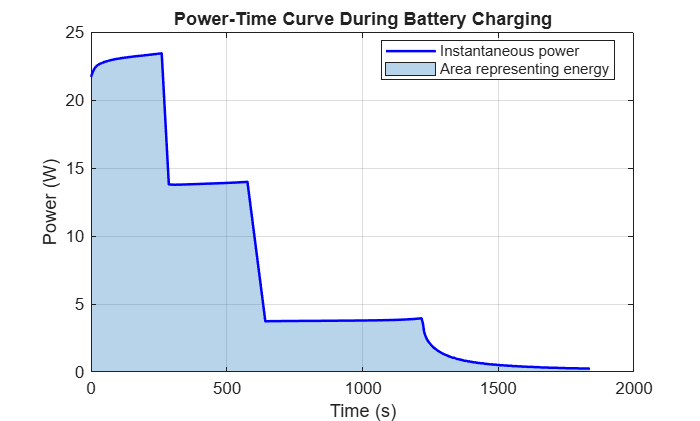

% Power-Time curve represent the total energy delivered
figure
area(time, power, 'FaceAlpha', 0.3)
hold on
plot(time, power, 'b', 'LineWidth',1.5)

xlabel('Time (s)')
ylabel('Power (W)')
title('Power-Time Curve During Battery Charging')
legend('Area representing energy', 'Instantaneous power', 'Location', 'best')

grid on

% To save the visualization as a PNG image.
exportgraphics(gcf, 'TASK3_POWERTIMECURVE_ENERGY.png', 'Resolution', 300);

The power-time curve shows that the battery initially receives the highest charging power. As charging progresses, the charger transition through different charging stages, reducing the charging current and therefore, the charging power. During the final stage, the power gradually decreases as the battery approaches full charge. The are under the curve is the total energy delivered.

**3.4 Estimate the energy loss due to the battery's internal resistance**

**    Apply Joule's Law:**

   The heating formula estimate power loss in watts.       

**     Power Loss:  **$
P_{\mathrm{loss}} = I^2R
\end{equation}$

 The Energy loss is given as:

    **Energy Loss: **$E_{\mathrm{loss}} = P_{\mathrm{loss}}*t
\end{equation}$

% Check is the internal resistance is constant
unique(chargeData.Internal_Resistance ...
    )

ans =     0.0170
    0.0176


Note: The internal resistance varies slightly overtime.

% Estimate Resistive energy loss

% Get internal resistance
R = chargeData.Internal_Resistance;
% Instantaneous Resistive power loss (W)
powerLoss = current.^2 .* R;

% Total Resistive energy loss (J)
energyLoss = trapz(time, powerLoss);

% Display values
fprintf('Total resistive energy loss = %.2f J\n', energyLoss);

Total resistive energy loss = 316.23 J


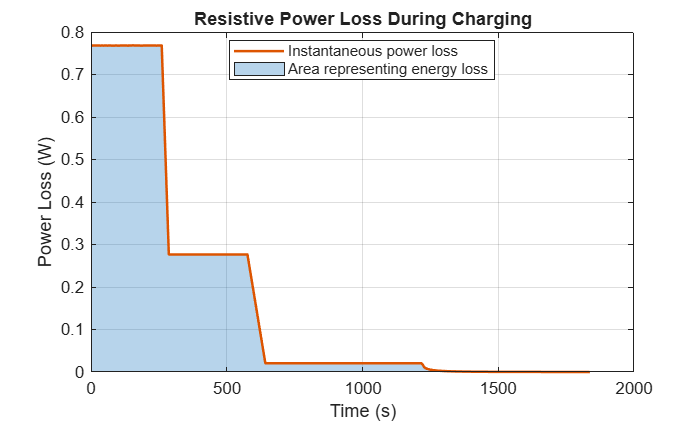

% Plot Power Loss vs Time

figure
% The area represents the energy loss
area(time, powerLoss, 'FaceAlpha', 0.3)
hold on
plot(time, powerLoss, 'LineWidth', 1.5)

xlabel('Time (s)')
ylabel('Power Loss (W)')
title('Resistive Power Loss During Charging')
legend('Area representing energy loss', 'Instantaneous power loss', 'Location', 'best')

grid on

% To save the visualization as a PNG image.
exportgraphics(gcf, 'TASK3_RESISTIVEPOWERLOSS.png', 'Resolution', 300);

**3.5 Save the results to a summary table.**


% Create summary table
% The results in the summary table correspond to the charging portion of
% Cycle 1. 

summaryTable = table( ...
    dVdt_beginning, dVdt_middle, dVdt_end, ...
    dVdt_beginning_RD, dVdt_middle_RD, dVdt_end_RD, ...
    dVdt_Cmax, dVdt_Cmin, ...
    dVdt_max, dVdt_min, ...
    time80, time100, ...
    energy, energyLoss, ...
    'VariableNames', { ...
    'Computed_dVdt_Beginning', ...
    'Computed_dVdt_Middle', ...
    'Computed_dVdt_End', ...
    'Raw_dVdt_Beginning', ...
    'Raw_dVdt_Middle', ...
    'Raw_dVdt_End', ...
    'Computed_dVdt_Max', ...
    'Computed_dVdt_Min', ...
    'Raw_dVdt_Max', ...
    'Raw_dVdt_Min', ...
    'Time_80', ...
    'Time_100', ...
    'Energy_Delivered', ...
    'Resistive_Energy_Loss'});

disp(summaryTable)

    Computed_dVdt_Beginning    Computed_dVdt_Middle    Computed_dVdt_End    Raw_dVdt_Beginning    Raw_dVdt_Middle    Raw_dVdt_End    Computed_dVdt_Max    Computed_dVdt_Min    Raw_dVdt_Max    Raw_dVdt_Min    Time_80    Time_100    Energy_Delivered    Resistive_Energy_Loss
    _______________________    ____________________    _________________    __________________    _______________    ____________    _________________    _________________    ____________    ____________    _______    ________    ________________    ___________